# OCT processing pipeline for 

## 1 Load volumetric OCT data

close all;clearvars;clc;
load('../Data/OCT_Example_vol.mat','BScans');

% Get volume dimensions
[nAxial,nAscan,nBscan] = size(BScans)

nAxial = 496

nAscan = 512

nBscan = 25

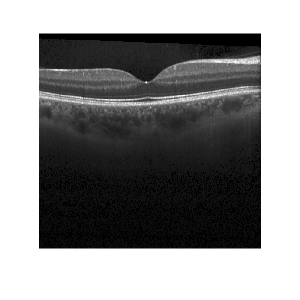


% Visualize central B-Scan
imshow(BScans(:,:,13));set(gcf,'Position',[100 100 300 300])

## 2 Load segmentation

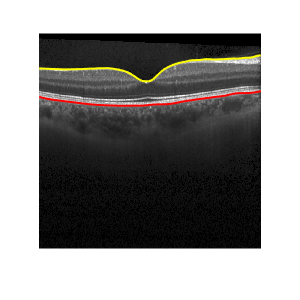

load('../Data/Ex.mat','X','Y','ILM','RPE','ScaleZ')
imshow(BScans(:,:,13)); hold on;set(gcf,'Position',[100 100 300 300])
plot(ILM(13,:),'y','LineWidth',1.5);
plot(RPE(13,:),'r','LineWidth',1.5);

## 3 Get total retinal thickness (flatten)

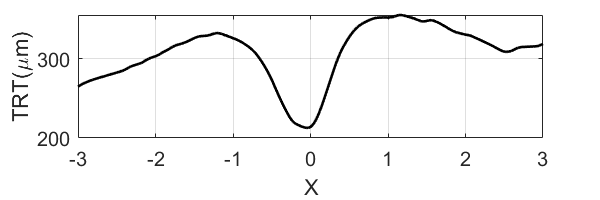

% Convert to micrometers and compute Total Retinal Thickness (TRT)
ILM = (nAxial-ILM)*ScaleZ;
RPE = (nAxial-RPE)*ScaleZ;
TRT = ILM - RPE;

% Plot thickness
figure;
plot(X(13,:),TRT(13,:),'k','LineWidth',2);
grid on;xlabel('X');ylabel('TRT(\mum)');set(gca,'FontSize',15);xlim([-3 3]);set(gcf,'Position',[0 10 600 200])

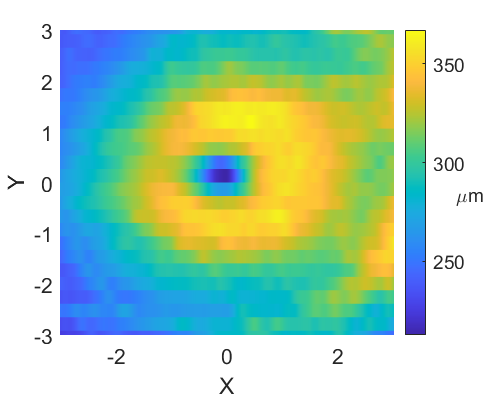

figure;
surf(X,Y,TRT,'EdgeColor','none');
xlabel('X');ylabel('Y');view(0,90);xlim([-3 3]);ylim([-3 3]);h = colorbar;ylabel(h,'\mum','Rotation',0);set(gca,'FontSize',16);set(gcf,'Position',[100 100 500 400]);

## 4 Alignment (based on AURA Tools [ ])

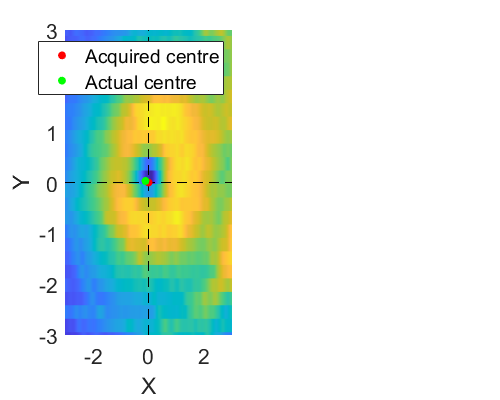

% Interpolate central region with a fine grid
[Xg,Yg] = meshgrid(-0.85:0.02:0.85,-0.85:0.02:0.85);
TRT_int = interp2(X,Y,TRT,Xg,Yg);
% Smooth interpolated TRT
m = (Xg.^2 + Yg.^2) < 0.05;
TRT_smooth = imfilter(TRT_int,double(m)/sum(m(:)),'replicate');
% Set center at the minimum of the smoothed surface
[~,indmin] = min(TRT_smooth(:));
[indx, indy] = ind2sub(size(TRT_smooth),indmin);
Xmin = Xg(indx,indy);
Ymin = Yg(indx,indy);
% Correct coordinates to align the heatmap (translation)
X = X - Xmin;
Y = Y - Ymin;

% Plot results
subplot(121);surf(X,Y,TRT,'EdgeColor','none','HandleVisibility',"off");view(0,90);hold on;
plot3([0 0],[-3 3],[max(TRT(:)) max(TRT(:))],'--k','HandleVisibility',"off");
plot3([-3 3],[0 0],[max(TRT(:)) max(TRT(:))],'--k','HandleVisibility',"off");
scatter3(0,0,max(TRT(:)),'r','filled');
scatter3(Xmin,Ymin,max(TRT(:)),'g','filled');
xlim([-3 3]);ylim([-3 3]);xlabel('X');ylabel('Y');legend('Acquired centre','Actual centre');set(gca,'FontSize',16);set(gcf,'Position',[0 0 500 400])

## 5 From Raster to Radial sampling

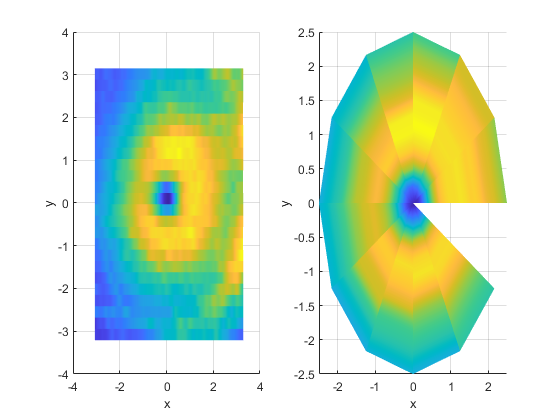

% Interpolate to radial
nAngles = 12;
maxRho = 2.5;
step = 0.01;

rho = 0:step:maxRho;
theta = linspace(0,2*pi,nAngles+1);theta(end) = [];
[Xrad,Yrad] = pol2cart(repmat(theta',1,length(rho)),repmat(rho,nAngles,1));
interpol = scatteredInterpolant(X(:),Y(:),TRT(:));
TRTrad = reshape(interpol(Xrad(:),Yrad(:)),size(Xrad));

figure;
subplot(121);surf(X,Y,TRT,'EdgeColor','none');view(0,90);xlabel('x');ylabel('y');
subplot(122);surf(Xrad,Yrad,TRTrad,'EdgeColor','none');view(0,90);xlabel('x');ylabel('y');

## 6 Fit pit model

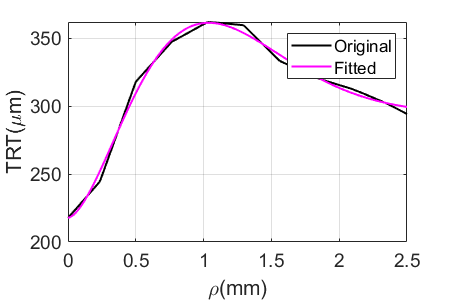

% Fitting configuration
x0 = [1 10 1 10]; 
lower = [0 0 0 0];
upper = [40 40 40 100];
fitfun = fittype(@(mu,sigma,gamma,alfa,x) ...
    mu*sigma^2.*x.^gamma.*exp(-mu.*x.^gamma)+alfa.*(1-exp(-mu.*x.^gamma)));    
options = fitoptions('StartPoint',x0,'Method','NonlinearLeastSquares',...
    'Lower',lower,'Upper',upper,'TolFun',1e-9,'TolX',1e-9,'MaxIter',1000);

TRTfit = nan(nAngles,size(TRTrad,2));

% Loop through all angular directions
for n=1:nAngles
    % Set pit to 0;
    minTRT = TRTrad(n,1);
    TRTaux = TRTrad(n,:) - minTRT;
    
    % Fit model
    [fitted,~] = fit(rho',TRTaux',fitfun,options);

    % Reconstruct curve
    TRTfit(n,:) = fitted(rho);

    % Add pit thickness 
    TRTfit(n,:) = TRTfit(n,:) + minTRT;    
end

% Plot central B-Scan
figure;
plot(rho,TRTrad(4,:),'k','LineWidth',1.5);hold on;
plot(rho,TRTfit(4,:),'m','LineWidth',1.5);
grid on;xlabel('\rho(mm)');ylabel('TRT(\mum)');legend('Original','Fitted');set(gca,'FontSize',14);set(gcf,'Position',[0 0 450 300])

## 7 Compute morphological parameters

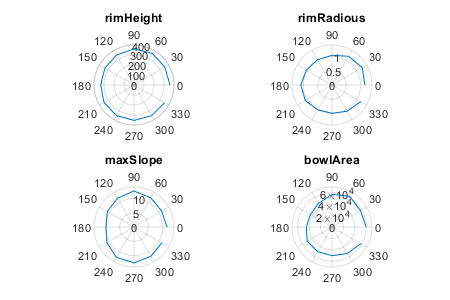

% Compute morphological parameters
maxSlope = nan(1,nAngles);
rimHeight = nan(1,nAngles);
rimRadious = nan(1,nAngles);
bowlArea = nan(1,nAngles);

scaleX = step*1e3;
for n=1:nAngles
    % Max Slope
    maxSlope(n) = atand(max(diff(TRTfit(n,:))./scaleX));
    % Rim Height
    [rimHeight(n),indRimHeight] = max(TRTfit(n,:));
    % Rim Radious
    rimRadious(n) = rho(indRimHeight);
    % Bowl Area
    areaSquare = scaleX*rimHeight(n)*(indRimHeight-2);
    areaUnderPit = scaleX*(TRTfit(n,1)/2 + sum(TRTfit(n,2:indRimHeight-1)) + TRTfit(n,indRimHeight)/2);
    bowlArea(n) = areaSquare - areaUnderPit;
end

% Plot Spider Results
subplot(221);polarplot(theta,rimHeight);title('rimHeight');
subplot(222);polarplot(theta,rimRadious);title('rimRadious');
subplot(223);polarplot(theta,maxSlope);title('maxSlope');
subplot(224);polarplot(theta,bowlArea);title('bowlArea');